Mp = 0.15;
zeta = -log(Mp)/(sqrt(pi^2 + log(Mp)^2));

ts = 4;
Wn = 4/(ts*zeta);

beta = acos(zeta);
beta = rad2deg(beta);
xpoint = -zeta*Wn;
tan_beta = tan((beta*pi)/180);
ypoint = tan_beta*zeta*Wn;

num1 = 15.25;
den1 = [1 13.9 15.24 0];
g1 = tf (num1,den1);
pole(g1);

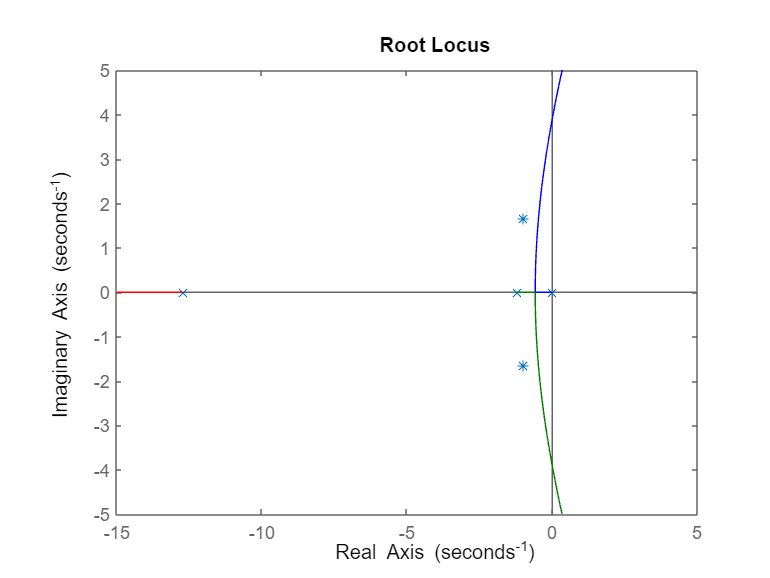

rlocusplot (g1);
xlim([-15, 5]);
ylim([-5, 5]);
hold on
points = [xpoint + ypoint*1i, xpoint - ypoint*1i];
plot(points, '*');
hold off

z = 1.2;
teta_p = 50;
x = ypoint/(tan((teta_p*pi)/180));
p = x + 1

p = 2.3895

s = -1.33 + 0.5j ;
num2 = 0.21*s;
den2 = (s+2.14)*s*s;
k = abs(den2/num2)

k = 6.4406

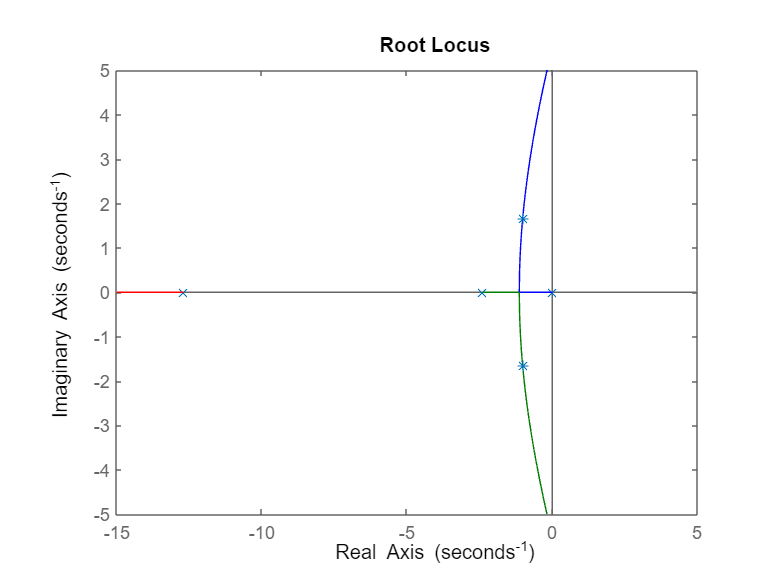

num3 = [k*15.25];
den3 = [1 12.7+p 12.7*p 0];
g2 = tf(num3,den3);
rlocusplot (g2);
xlim([-15, 5]);
ylim([-5, 5]);
hold on
points = [xpoint + ypoint*1i, xpoint - ypoint*1i];
plot(points, '*');
hold on

%sisotool(g2)

K_old = (k*15.25)/(12.7*p);
K_new = 34;
z2 = 0.1/10

z2 = 0.0100

p2 = (z2*K_old)/K_new

p2 = 9.5192e-04

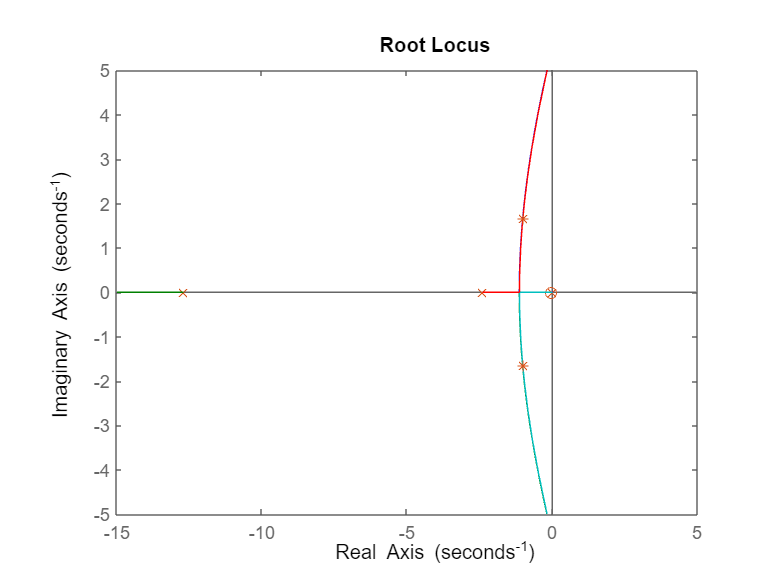

num4 = [k*15.25 k*15.25*z2];
den4 = [1 p+12.7+p2 (12.7+p)*p2+p*12.7 p2*p*12.7 0];
g3 = tf(num4,den4);
h = rlocusplot (g3);
xlim([-15, 5]);
ylim([-5, 5]);
hold on
points = [xpoint + ypoint*1i, xpoint - ypoint*1i];
plot(points, '*');
hold off

sisotool(g3)